vel_ser = 9600;
seriali_disponibili = serialportlist('available');
if (exist('ser'))
    delete(ser);
    clear ser;
end

seriale_micro = seriali_disponibili(end);
disp(seriale_micro)

COM6


ser = serialport (seriale_micro,vel_ser, Timeout = 5);
configureTerminator(ser, "CR");

stringa = "w"

stringa = "w"

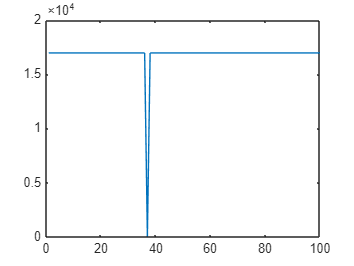

ser.flush;
ser.writeline(stringa);
vet = ser.read(100, "uint16");
plot(vet)


delete(ser)
clear("ser")